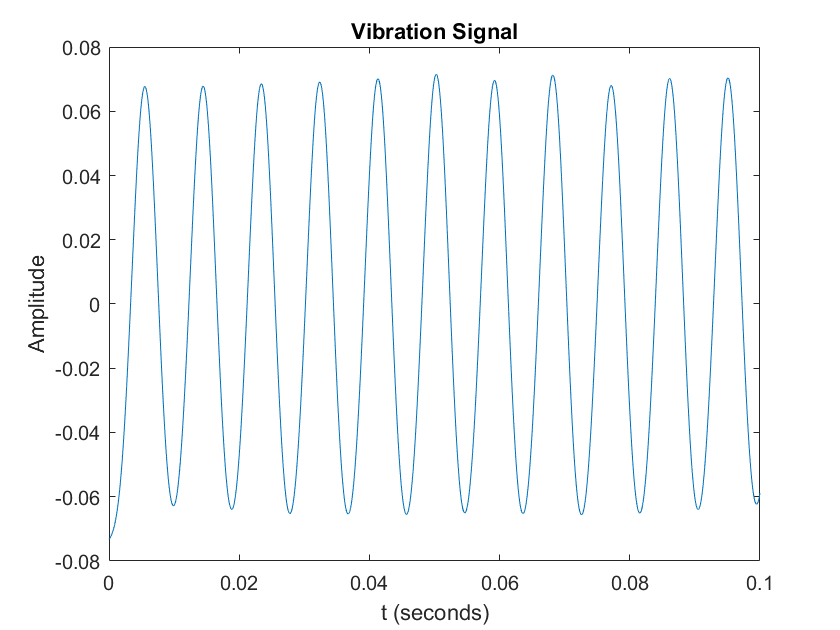

Fs = 100000;          % Sampling frequency (100 kHz)                   
T = 1/Fs;             % Sampling period       
L = 100;              % Length of signal (100 milliseconds)
t = 0:T:0.1-T;        % Time vector

%plot the signal
plot(t,x)
title('Vibration Signal')
xlabel('t (seconds)')
ylabel('Amplitude')

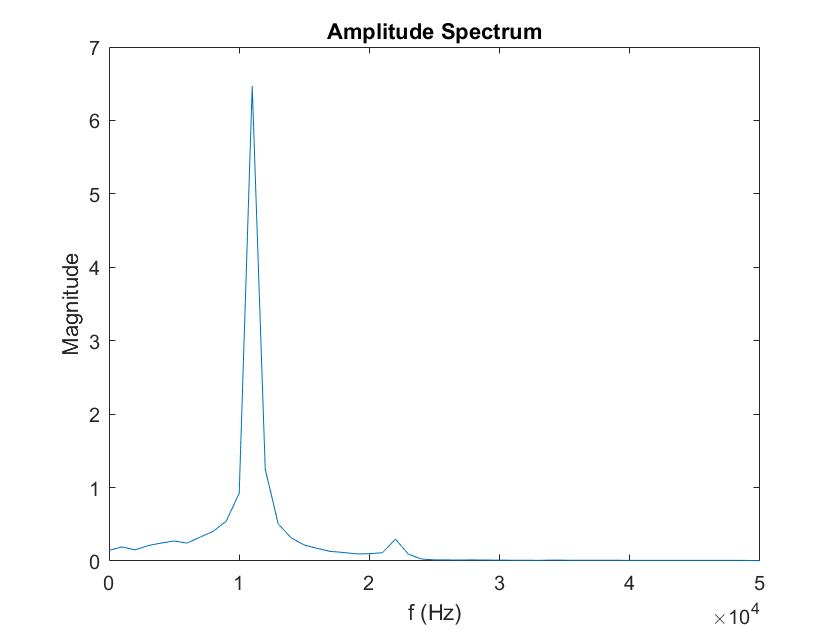



Y = fft(x);

f = Fs*(0:(L/2))/L;
P2 = abs(Y/L);
P1 = P2(1:L/2+1);
P1(2:end-1) = 2*P1(2:end-1);

plot(f,P1) 
title('Amplitude Spectrum')
xlabel('f (Hz)')
ylabel('Magnitude')